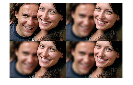

%{

YOUR COMMENTS:

Please include brief comments here describing the effects and quality of
results (3-5 lines).  Include anything else about the images you would like
to share.

This desired effect is to blur out the background after acquiring a mask of
the foreground of some image without leaving any artifacting surrounding
the foreground masked area, which some techniques would leave. However, the
technique dividing each pixel value by the weight of the blurred mask
achieves a blurred background result with unnoticible levels of
artifacting. In my examples, I noticed that for pictures with smaller
details in the foreground that a lower radius of the blurring gaussion for the bokeh effect
was preferable, otherwise the difference between the two seemed unnatural
and not pleasant. On the other hand, images with larger and simpler
foregrounds preferred a somewhat larger radius, as blurring out the details
at a larger scale made sense with the size of the foreground details.



(Optional) Also mention if you obtained more compelling results by using a 
different filter shape than a disk.

%}

close('all');   % close all open figures so we start with a clean slate!

I=im2double(imread('couple.jpg'));

% Get foreground mask (part that stays sharp) from the user

% For the given image, a mask is provided as an image
mask = im2double(imread('mask.png'));

% Define the bokeh filter shape
% A simple disk filter is provided as default
% For extra credit you may optionally define a different shape, e.g., hexagon, starburst, heart etc.

radius = 15;            % choose this carefully for each image
bokeh_shape = fspecial('disk', radius);

result1a = method1(I, mask, bokeh_shape);
result1b = method2(I, mask, bokeh_shape);
result1 = method3(I, mask, bokeh_shape);

figure; montage({I, result1a, result1b, result1});



%%
% -------------------------------------------------------------------------
% IMPORTANT NOTE (please read carefully)
% -------------------------------------------------------------------------
% Repeat your method for 5 more sets of images.  But remember that for
% these you must interactively specify the mask ONE TIME.
%
% Work in the Matlab computer app or the full Matlab Online version
% (https://matlab.mathworks.com) first to get the coordinates for alignment
% and cropping.  Then hard-code these in your program before migrating to
% the Matlab Grader website for submission.
%
% -------------------------------------------------------------------------

% My photo!
I=im2double(imread('https://scontent-iad3-2.cdninstagram.com/v/t51.2885-15/38923036_255954675044529_2003528327196835840_n.jpg?stp=dst-jpg_e35&_nc_ht=scontent-iad3-2.cdninstagram.com&_nc_cat=109&_nc_ohc=GxJG3pJySRwAX8maQ-P&edm=ABfd0MgBAAAA&ccb=7-4&oh=00_AT_jbISvGhhSPYXCy9Ou_DJYwo9nznRiSJPBhHItH4qePQ&oe=624C37E8&_nc_sid=7bff83'));

% Interactively draw the foreground mask as a polygon

%[poly_x, poly_y] = getPolygonForMask(I);
disp("Copy the values of the vectors poly_x and poly_y from the " + ...
    "Command Window below and hard code them inside your code for " + ...
    "submission via the Grader website.");

Copy the values of the vectors poly_x and poly_y from the Command Window below and hard code them inside your code for submission via the Grader website.


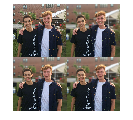

%poly_x        % display x coords of polygon
%poly_y        % display y coords of polygon
% Once you have these coordinates, comment out the call to getPolygonForMask() 
% and hard code the coordinates instead.
poly_x = [81.8127413127411	87.0809990906516	89.8627107526722	91.2535665836825	94.0352782457030	99.5987015697441	103.771269062775	110.725548217826	119.070683203888	121.852394865908	127.415818189950	119.070683203888	103.771269062775	89.8627107526722	74.5632966115593	81.5175757666106	91.2535665836825	100.989557400754	107.943836555806	113.507259879847	126.024962358939	127.415818189950	123.243250696919	127.415818189950	130.197529851970	130.197529851970	144.106088162073	156.623790641165	173.314060613288	191.395186416422	203.912888895514	221.994014698648	240.075140501781	251.201987149864	255.374554642894	260.937977966936	269.283112952997	266.501401290977	262.328833797946	256.765410473905	248.420275487843	241.465996332792	230.339149684710	224.775726360669	219.212303036627	208.085456388545	209.476312219555	212.258023881576	219.212303036627	206.694600557535	201.131177233494	195.567753909453	194.176898078443	202.522033064504	212.258023881576	221.994014698648	224.775726360669	245.638563825823	263.719689628956	283.191671263100	308.227076221285	324.917346193408	340.216760334521	352.734462813613	363.861309461696	374.988156109778	383.333291095839	387.505858588870	388.896714419880	386.115002757860	394.460137743921	398.632705236952	398.632705236952	397.241849405942	390.287570250891	388.896714419880	386.115002757860	380.551579433819	373.597300278767	373.597300278767	369.424732785737	373.597300278767	376.379011940788	379.160723602809	391.678426081901	401.414416898973	412.541263547055	426.449821857158	443.140091829281	454.266938477363	472.348064280497	482.084055097568	493.210901745651	504.337748393733	521.028018365856	529.373153351918	537.718288337979	551.626846648082	571.098828282226	585.007386592329	598.915944902431	610.042791550514	625.342205691626	635.078196508698	625.342205691626	616.997070705565	614.215359043544	610.042791550514	605.870224057483	601.697656564452	603.088512395462	603.088512395462	598.915944902431	598.915944902431	596.134233240411	600.306800733442	600.306800733442	598.915944902431	600.306800733442	590.570809916370	580.834819099298	572.489684113236	568.317116620205	568.317116620205	571.098828282226	576.662251606267	582.225674930308	589.179954085359	597.525089071421	603.088512395462	612.824503212534	619.778782367585	623.951349860616	633.687340677688	643.423331494760	661.504457297894	672.631303945976	685.149006425068	700.448420566181	718.529546369315	729.656393017397	750.519230482551	769.991212116695	783.899770426797	789.463193750838	788.072337919828	782.508914595787	786.681482088818	788.072337919828	785.290626257808	783.899770426797	785.290626257808	785.290626257808	786.681482088818	785.290626257808	785.290626257808	789.463193750838	795.026617074880	799.199184567910	796.417472905890	795.026617074880	793.635761243869	788.072337919828	775.554635440736	769.991212116695	764.427788792653	763.036932961643	761.646077130633	761.646077130633	761.646077130633	779.727202933766	789.463193750838	811.716887047003	821.452877864075	832.579724512157	838.143147836198	846.488282822259	847.879138653270	850.660850315290	850.660850315290	864.569408625393	874.305399442465	879.868822766506	893.777381076609	904.904227724691	907.685939386711	914.640218541763	924.376209358834	931.330488513886	942.457335161968	942.457335161968	942.457335161968	950.802470148030	957.756749303081	959.147605134091	957.756749303081	963.320172627122	971.665307613184	977.228730937225	977.228730937225	977.228730937225	975.837875106215	980.010442599245	982.792154261266	980.010442599245	977.228730937225	978.619586768235	978.619586768235	978.619586768235	981.401298430256	984.183010092276	989.746433416317	992.528145078338	998.091568402379	1003.65499172642	1006.43670338844	989.746433416317	981.401298430256	982.792154261266	984.183010092276	986.964721754297	984.183010092276	980.010442599245	973.056163444194	970.274451782174	967.492740120153	961.929316796112];
poly_y = [1081.19498069498	1062.41842697634	1024.86531953906	985.921356270777	942.804825509458	913.596853058243	884.388880607027	856.571763986822	834.318070690657	814.846089056514	793.983251591360	784.247260774288	781.465549112267	773.120414126205	756.430144154082	736.958162519938	710.531901730743	681.323929279528	664.633659307404	640.989110180230	624.298840208106	603.436002742952	588.136588601839	565.882895305675	549.192625333552	535.284067023449	529.720643699408	519.984652882336	507.466950403244	499.121815417182	493.558392093141	493.558392093141	497.730959586172	504.685238741223	496.340103755162	494.949247924151	493.558392093141	483.822401276069	469.913842965966	456.005284655864	443.487582176771	425.406456373638	417.061321387576	408.716186401515	398.980195584443	387.853348936360	373.944790626258	369.772223133227	362.817943978176	353.081953161104	335.000827357970	311.356278230796	277.975738286549	257.112900821395	250.158621666344	244.595198342303	233.468351694220	226.514072539169	216.778081722097	216.778081722097	216.778081722097	219.559793384118	230.686640032200	232.077495863210	239.031775018261	254.331189159374	275.194026624529	304.401999075744	326.655692371909	337.782539019991	335.000827357970	341.955106513022	355.863664823124	368.381367302217	376.726502288278	390.635060598381	397.589339753432	403.152763077473	401.761907246463	428.188168035658	439.315014683740	451.832717162833	467.132131303946	482.431545445059	490.776680431120	492.167536262131	493.558392093141	496.340103755162	506.076094572233	507.466950403244	504.685238741223	494.949247924151	486.604112938090	483.822401276069	475.477266290008	457.396140486874	450.441861331823	437.924158852730	430.969879697679	425.406456373638	426.797312204648	428.188168035658	421.233888880607	412.888753894545	394.807628091412	382.289925612319	364.208799809186	366.990511471206	361.427088147165	353.081953161104	348.909385668073	343.345962344032	329.437404033929	318.310557385847	308.574566568775	307.183710737765	294.666008258672	283.539161610590	269.630603300487	264.067179976446	258.503756652405	262.676324145436	250.158621666344	241.813486680282	232.077495863210	219.559793384118	209.823802567046	200.087811749974	195.915244256943	194.524388425933	188.960965101892	179.224974284820	173.661550960779	168.098127636738	165.316415974717	158.362136819666	154.189569326635	152.798713495625	154.189569326635	154.189569326635	155.580425157645	162.534704312696	166.707271805727	170.879839298758	176.443262622799	186.179253439871	195.915244256943	207.042090905025	220.950649215128	232.077495863210	243.204342511292	252.940333328364	261.285468314426	269.630603300487	283.539161610590	291.884296596652	294.666008258672	296.056864089683	304.401999075744	312.747134061806	325.264836540898	335.000827357970	350.300241499083	355.863664823124	355.863664823124	354.472808992114	369.772223133227	383.680781443330	394.807628091412	408.716186401515	415.670465556566	418.452177218586	426.797312204648	432.360735528689	439.315014683740	449.051005500812	462.959563810915	472.695554627987	486.604112938090	497.730959586172	504.685238741223	500.512671248192	493.558392093141	493.558392093141	501.903527079203	510.248662065264	513.030373727285	515.812085389305	518.593797051326	524.157220375367	528.329787868398	532.502355361429	538.065778685470	545.020057840521	554.756048657593	556.146904488603	561.710327812644	565.882895305675	568.664606967696	575.618886122747	582.573165277798	586.745732770829	595.090867756891	608.999426066994	615.953705222045	627.080551870127	638.207398518209	656.288524321343	677.151361786497	693.841631758620	709.141045899733	735.567306688928	757.820999985093	780.074693281257	803.719242408431	834.318070690657	842.663205676719	844.054061507729	866.307754803894	901.079150579150	941.413969678448	970.621942129664	995.657347087849	1033.21045452513	1054.07329199028	1066.59099446937	1081.89040861049];

mask = poly2mask(poly_x, poly_y, size(I, 1), size(I, 2));

% Define the bokeh filter shape
% A simple disk filter is provided as default
% For extra credit you may optionally define a different shape, e.g., hexagon, starburst, heart etc.

radius = 14;            % choose this carefully for each image
bokeh_shape = fspecial('disk', radius);

result2a = method1(I, mask, bokeh_shape);
result2b = method2(I, mask, bokeh_shape);
result2 = method3(I, mask, bokeh_shape);

figure; montage({I, result2a, result2b, result2});




% REPEAT ABOVE FOR IMAGE 3

I=im2double(imread('https://scontent-atl3-1.cdninstagram.com/v/t51.2885-15/33740405_568375063563721_3057099545960775680_n.jpg?stp=dst-jpg_e35&_nc_ht=scontent-atl3-1.cdninstagram.com&_nc_cat=101&_nc_ohc=RTXe7sqbKHQAX8SecTj&edm=ALQROFkBAAAA&ccb=7-4&ig_cache_key=MTc5MjMxMjk0MjQ0OTA2NzkyOA%3D%3D.2-ccb7-4&oh=00_AT-H7XAVblOXnzE8pjG6nyRPnDR3krgP1TcLDcQBvQz_xg&oe=624CBB54&_nc_sid=30a2ef'));

% Interactively draw the foreground mask as a polygon

%[poly_x, poly_y] = getPolygonForMask(I);
disp("Copy the values of the vectors poly_x and poly_y from the " + ...
    "Command Window below and hard code them inside your code for " + ...
    "submission via the Grader website.");

Copy the values of the vectors poly_x and poly_y from the Command Window below and hard code them inside your code for submission via the Grader website.


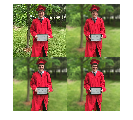

%poly_x        % display x coords of polygon
%poly_y        % display y coords of polygon
% Once you have these coordinates, comment out the call to getPolygonForMask() 
% and hard code the coordinates instead.
poly_x = [368.144787644788	372.314671814672	377.874517374517	382.044401544401	384.824324324324	390.384169884170	394.554054054054	395.944015444015	400.113899613900	405.673745173745	404.283783783784	398.723938223938	397.333976833977	393.164092664093	372.314671814672	357.025096525096	351.465250965251	351.465250965251	352.855212355212	355.635135135135	362.584942084942	368.144787644788	373.704633204633	383.434362934363	393.164092664093	400.113899613900	405.673745173745	426.523166023166	448.762548262548	475.171814671815	498.801158301158	508.530888030888	515.480694980695	515.480694980695	514.090733590733	507.140926640926	497.411196911197	500.191119691119	501.581081081081	504.361003861004	490.461389961390	462.662162162162	479.341698841699	502.971042471042	533.550193050193	582.198841698842	623.897683397683	682.276061776062	637.797297297297	637.797297297297	637.797297297297	640.577220077220	636.407335907336	630.847490347490	629.457528957529	622.507722007722	618.337837837838	612.777992277992	611.388030888031	622.507722007722	647.527027027027	675.326254826255	685.055984555984	697.565637065637	707.295366795367	721.194980694981	739.264478764479	750.384169884170	762.893822393822	771.233590733591	772.623552123552	778.183397683398	780.963320463320	780.963320463320	780.963320463320	780.963320463320	786.523166023166	789.303088803089	794.862934362934	801.812741312741	803.202702702703	801.812741312741	776.793436293436	730.924710424710	721.194980694981	715.635135135135	715.635135135135	714.245173745174	717.025096525096	719.805019305019	718.415057915058	708.685328185328	700.345559845560	700.345559845560	698.955598455598	697.565637065637	690.615830115830	693.395752895753	692.005791505791	697.565637065637	700.345559845560];
poly_y = [1078.41505791506	1029.76640926641	996.407335907336	944.978764478764	914.399613899614	881.040540540540	837.951737451737	818.492277992278	778.183397683397	754.554054054054	728.144787644788	692.005791505791	671.156370656370	653.086872586872	623.897683397683	596.098455598455	573.859073359073	553.009652509652	480.731660231660	466.832046332046	454.322393822394	443.202702702703	415.403474903475	384.824324324324	359.805019305019	334.785714285714	319.496138996139	311.156370656371	304.206563706564	293.086872586872	279.187258687259	273.627413127413	258.337837837838	240.268339768340	220.808880308880	216.638996138996	184.669884169884	179.110038610039	166.600386100386	149.920849420849	138.801158301158	133.241312741313	104.052123552123	63.7432432432432	20.6544401544402	35.9440154440154	51.2335907335907	79.0328185328185	140.191119691120	166.600386100386	181.889961389961	186.059845559845	199.959459459459	209.689189189189	223.588803088803	227.758687258687	234.708494208494	249.998069498069	256.947876447876	266.677606177606	276.407335907336	284.747104247104	284.747104247104	284.747104247104	293.086872586872	308.376447876448	327.835907335907	362.584942084942	426.523166023166	471.001930501930	484.901544401544	497.411196911197	514.090733590733	523.820463320463	540.500000000000	562.739382239382	601.658301158301	615.557915057915	626.677606177606	648.916988416988	669.766409266409	683.666023166023	689.225868725869	694.785714285714	705.905405405405	717.025096525096	737.874517374517	764.283783783784	812.932432432432	840.731660231660	875.480694980695	906.059845559845	935.249034749035	946.368725868726	956.098455598455	965.828185328185	964.438223938224	979.727799227799	1028.37644787645	1054.78571428571	1079.80501930502];

mask = poly2mask(poly_x, poly_y, size(I, 1), size(I, 2));

% Define the bokeh filter shape
% A simple disk filter is provided as default
% For extra credit you may optionally define a different shape, e.g., hexagon, starburst, heart etc.

radius = 15;            % choose this carefully for each image
bokeh_shape = fspecial('disk', radius);

result3a = method1(I, mask, bokeh_shape);
result3b = method2(I, mask, bokeh_shape);
result3 = method3(I, mask, bokeh_shape);

figure; montage({I, result3a, result3b, result3});



% REPEAT ABOVE FOR IMAGE 4
I=im2double(imread('https://media.discordapp.net/attachments/176350047766708224/945809677701230592/IMG_2525.jpg?width=507&height=676'));

% Interactively draw the foreground mask as a polygon

%[poly_x, poly_y] = getPolygonForMask(I);
disp("Copy the values of the vectors poly_x and poly_y from the " + ...
    "Command Window below and hard code them inside your code for " + ...
    "submission via the Grader website.");

Copy the values of the vectors poly_x and poly_y from the Command Window below and hard code them inside your code for submission via the Grader website.


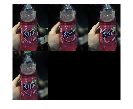

%poly_x        % display x coords of polygon
%poly_y        % display y coords of polygon
% Once you have these coordinates, comment out the call to getPolygonForMask() 
% and hard code the coordinates instead.
poly_x = [1.69626769626763	4.30630630630623	5.17631917631911	11.2664092664092	19.9665379665379	29.5366795366795	36.4967824967824	45.1969111969111	51.2870012870012	57.3770913770913	65.2072072072071	72.1673101673101	83.4774774774774	93.0476190476190	101.747747747748	114.797940797941	125.238095238095	133.068211068211	139.158301158301	144.378378378378	144.378378378378	146.118404118404	148.728442728443	150.468468468468	152.208494208494	151.338481338481	152.208494208494	154.818532818533	156.558558558558	163.518661518661	179.178893178893	186.138996138996	193.099099099099	201.799227799228	207.889317889318	209.629343629344	207.889317889318	203.539253539253	199.189189189189	200.059202059202	200.059202059202	200.059202059202	201.799227799228	203.539253539253	288.800514800515	289.670527670528	292.280566280566	294.020592020592	295.760617760618	291.410553410553	288.800514800515	288.800514800515	291.410553410553	300.110682110682	307.070785070785	316.640926640927	325.341055341055	332.301158301158	341.001287001287	347.091377091377	351.441441441441	352.311454311454	351.441441441441	352.311454311454	356.661518661519	360.141570141570	361.881595881596	364.491634491634	365.361647361647	362.751608751609	361.011583011583	358.401544401544	357.531531531531	358.401544401544	360.141570141570	361.881595881596	361.881595881596	362.751608751609	364.491634491634	366.231660231660	368.841698841699	370.581724581725	374.061776061776	376.671814671815	377.541827541827	374.061776061776	368.841698841699	362.751608751609	356.661518661519	354.921492921493	354.051480051480	0.559764397602294];
poly_y = [473.351994851995	467.261904761905	454.211711711712	439.421492921493	426.371299871300	413.321106821107	402.010939510940	391.570785070785	381.130630630631	375.040540540541	365.470398970399	358.510296010296	349.810167310167	340.240025740026	335.019948519949	321.969755469756	309.789575289575	301.959459459460	298.479407979408	296.739382239382	287.169240669241	278.469111969112	265.418918918919	247.148648648649	233.228442728443	216.698198198198	201.907979407979	184.507722007722	163.627413127413	148.837194337194	126.216859716860	114.036679536680	100.986486486486	82.7162162162163	74.0160875160875	64.4459459459459	59.2258687258687	53.1357786357787	41.8256113256114	35.7355212355212	29.6454311454312	20.0752895752896	12.2451737451738	1.80501930501930	1.80501930501930	17.4652509652510	28.7754182754183	39.2155727155728	46.1756756756757	56.6158301158301	62.7059202059202	73.1460746460747	83.5862290862291	94.8963963963964	106.206563706564	117.516731016731	129.696911196911	139.267052767053	151.447232947233	167.107464607465	177.547619047619	191.467824967825	210.608108108108	226.268339768340	238.448519948520	249.758687258687	262.808880308880	280.209137709138	296.739382239382	308.919562419562	318.489703989704	328.929858429859	346.330115830116	369.820463320463	398.530888030888	424.631274131274	457.691763191763	477.702059202059	500.322393822394	519.462676962677	542.953024453025	555.133204633205	563.833333333333	581.233590733591	597.763835263835	621.254182754183	638.654440154440	654.314671814672	667.364864864865	676.064993564994	679.545045045045	678.234147274688];

mask = poly2mask(poly_x, poly_y, size(I, 1), size(I, 2));

% Define the bokeh filter shape
% A simple disk filter is provided as default
% For extra credit you may optionally define a different shape, e.g., hexagon, starburst, heart etc.

radius = 14;            % choose this carefully for each image
bokeh_shape = fspecial('disk', radius);

result4a = method1(I, mask, bokeh_shape);
result4b = method2(I, mask, bokeh_shape);
result4 = method3(I, mask, bokeh_shape);

figure; montage({I, result4a, result4b, result4});


% REPEAT ABOVE FOR IMAGE 5

I=im2double(imread('https://cdn.discordapp.com/attachments/187289110539534336/958877353310838904/FB_IMG_1646590990556.jpg'));

% Interactively draw the foreground mask as a polygon

%[poly_x, poly_y] = getPolygonForMask(I);
disp("Copy the values of the vectors poly_x and poly_y from the " + ...
    "Command Window below and hard code them inside your code for " + ...
    "submission via the Grader website.");

Copy the values of the vectors poly_x and poly_y from the Command Window below and hard code them inside your code for submission via the Grader website.


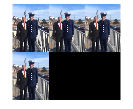

%poly_x        % display x coords of polygon
%poly_y        % display y coords of polygon
% Once you have these coordinates, comment out the call to getPolygonForMask() 
% and hard code the coordinates instead.
poly_x = [109.187898089172	122.640127388535	140.984076433121	161.773885350318	167.888535031847	185.009554140127	193.570063694267	191.124203821656	187.455414012739	183.786624203821	186.232484076433	185.009554140127	185.009554140127	186.232484076433	193.570063694267	210.691082802548	226.589171974522	242.487261146497	258.385350318471	269.391719745223	273.060509554140	277.952229299363	276.729299363057	273.060509554140	273.060509554140	271.837579617834	269.391719745223	264.500000000000	260.831210191083	262.054140127388	265.722929936306	275.506369426751	280.398089171974	282.843949044586	284.066878980892	286.512738853503	314.640127388535	341.544585987261	346.436305732484	350.105095541401	347.659235668790	343.990445859872	341.544585987261	339.098726114650	334.207006369427	334.207006369427	335.429936305732	336.652866242038	337.875796178344	335.429936305732	332.984076433121	332.984076433121	330.538216560509	324.423566878981	319.531847133758	319.531847133758	325.646496815286	348.882165605095	378.232484076433	408.805732484076	427.149681528662	438.156050955414	444.270700636942	450.385350318471	445.493630573248	439.378980891720	427.149681528662	421.035031847134	424.703821656051	425.926751592356	425.926751592356	421.035031847134	418.589171974522	416.143312101911	413.697452229299	413.697452229299	417.366242038216	425.926751592356	443.047770700637	463.837579617834	484.627388535032	499.302547770700	504.194267515923	510.308917197452	513.977707006369	515.200636942675	517.646496815286	513.977707006369	513.977707006369	513.977707006369	513.977707006369	511.531847133758	506.640127388535	504.194267515923	500.525477707006	496.856687898089	489.519108280255	476.066878980891	473.621019108280	467.506369426751	462.614649681528	456.500000000000	446.716560509554	451.608280254777	451.608280254777	454.054140127388	451.608280254777	443.047770700637	432.041401273885	332.966550367155	329.235797170619	334.139985849738	335.366033019518	326.783702831060	323.105561321721	319.427419812382	316.975325472823	309.619042454145	310.845089623925	309.619042454145	299.810665095908	296.132523586570	287.550193398112	282.646004718994	286.324146228332	288.776240567892	285.098099058553	285.098099058553	288.776240567892	285.098099058553	276.515768870095	276.515768870095	283.872051888773	292.454382077231	303.488806605247	156.233122757954	152.552638483322	150.098982300235	150.098982300235	151.325810391779	151.325810391779	150.098982300235	148.872154208691	143.964841842516	137.830701384797	137.830701384797	143.964841842516	143.964841842516	141.511185659428	135.377045201709	130.469732835534	120.655108103183	118.201451920095	110.840483370832	107.159999096201	98.5722024553943	96.1185462723066	92.4380619976752	89.9844058145875	92.4380619976752	97.3453743638505	96.1185462723066	99.7990305469381	104.706342913113];
poly_y = [381.442675159236	375.328025477707	369.213375796178	364.321656050955	355.761146496815	343.531847133758	341.085987261147	332.525477707006	325.187898089172	315.404458598726	306.843949044586	297.060509554140	283.608280254777	271.378980891720	261.595541401274	253.035031847134	249.366242038217	255.480891719745	265.264331210191	278.716560509554	287.277070063694	293.391719745223	303.175159235669	306.843949044586	315.404458598726	326.410828025478	333.748407643312	343.531847133758	349.646496815287	354.538216560510	356.984076433121	356.984076433121	356.984076433121	356.984076433121	344.754777070064	339.863057324841	327.633757961783	316.627388535032	308.066878980892	303.175159235669	293.391719745223	279.939490445860	275.047770700637	268.933121019108	259.149681528663	254.257961783440	253.035031847134	246.920382165605	242.028662420382	234.691082802548	227.353503184713	223.684713375796	217.570063694268	210.232484076433	195.557324840764	184.550955414013	175.990445859873	162.538216560510	162.538216560510	168.652866242038	178.436305732484	188.219745222930	198.003184713376	209.009554140127	217.570063694268	226.130573248408	235.914012738854	245.697452229299	249.366242038217	253.035031847134	261.595541401274	270.156050955414	275.047770700637	278.716560509554	286.054140127389	290.945859872611	300.729299363057	306.843949044586	312.958598726115	321.519108280255	326.410828025478	331.302547770701	342.308917197452	369.213375796178	386.334394904459	412.015923566879	438.920382165605	469.493630573248	482.945859872611	506.181528662420	550.207006369427	567.328025477707	591.786624203822	618.691082802548	635.812101910828	650.487261146497	657.824840764331	666.385350318471	672.500000000000	677.391719745223	690.843949044586	739.761146496815	782.563694267516	843.710191082803	879.175159235669	902.410828025478	928.092356687898	954.996815286624	961.111464968153	962.947028277009	941.491202805865	925.552589598730	908.387929221816	845.859523563054	818.886485827903	795.591589602090	775.974834885616	758.810174508701	741.645514131786	713.446429226854	675.438966963686	726.932948094430	742.871561301566	762.488316018040	782.105070734514	805.399966960327	828.694863186140	849.537665072393	867.928372619088	888.771174505341	905.935834882256	923.100495259171	939.039108466306	947.621438654764	963.560051861899	954.358841175320	946.997872626057	921.234482703637	893.017436598129	863.573562401077	832.902860112482	797.324845457711	769.107799352203	751.932206070590	733.529784697433	726.168816148170	708.993222866556	699.178598134206	695.498113859574	705.312738591925	716.354191415819	711.446879049644	702.859082408837	679.549348669504	672.188380120241	662.373755387891	648.878646380909	619.434772183857	576.495788979824	536.010461958877	505.339759670282	472.215401198599	437.864214635372	403.513028072145];

mask = poly2mask(poly_x, poly_y, size(I, 1), size(I, 2));

% Define the bokeh filter shape
% A simple disk filter is provided as default
% For extra credit you may optionally define a different shape, e.g., hexagon, starburst, heart etc.

radius = 6;            % choose this carefully for each image
bokeh_shape = fspecial('disk', radius);

result5a = method1(I, mask, bokeh_shape);
result5b = method2(I, mask, bokeh_shape);
result5 = method3(I, mask, bokeh_shape);

figure; montage({I, result5a, result5b, result5});



% REPEAT ABOVE FOR IMAGE 6

I=im2double(imread('https://cdn.discordapp.com/attachments/187289110539534336/958877425532538960/IMG_20220212_155015.jpg'));

% Interactively draw the foreground mask as a polygon

%[poly_x, poly_y] = getPolygonForMask(I);
disp("Copy the values of the vectors poly_x and poly_y from the " + ...
    "Command Window below and hard code them inside your code for " + ...
    "submission via the Grader website.");

Copy the values of the vectors poly_x and poly_y from the Command Window below and hard code them inside your code for submission via the Grader website.


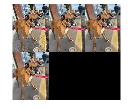

%poly_x        % display x coords of polygon
%poly_y        % display y coords of polygon
% Once you have these coordinates, comment out the call to getPolygonForMask() 
% and hard code the coordinates instead.
poly_x = [279.480891719745	283.355450525376	291.513509675849	297.632054038703	299.671568826321	295.592539251085	293.553024463467	295.592539251085	299.671568826321	299.671568826321	299.671568826321	297.632054038703	297.632054038703	297.632054038703	299.671568826321	299.671568826321	305.790113189176	305.790113189176	303.750598401557	301.711083613939	313.948172339648	322.106231490121	324.145746277739	322.106231490121	289.473994888230	267.039332224431	248.683699135867	230.328066047304	214.011947746358	197.695829445413	185.458740719704	191.577285082559	193.616799870177	203.814373808268	209.932918171122	216.051462533977	226.249036472067	236.446610410158	252.762728711103	256.841758286340	256.841758286340	236.446610410158	216.051462533977	201.774859020650	195.656314657795	195.656314657795	191.577285082559	185.458740719704	177.300681569232	173.221651993995	167.103107631141	148.747474542577	134.470871029250	120.194267515923	112.036208365450	101.838634427360	93.6805752768871	81.4434865511780	69.2063978254691	63.0878534626147	63.0878534626147	67.1668830378510	71.2459126130873	79.4039717635599	97.7596048521234	118.154752728305	142.628930179723	179.340196356850	205.853888595886	228.288551259686	256.841758286340	283.355450525376	307.829627976794	330.264290640594	346.580408941539	360.857012454866	383.291675118666	397.568278631993	409.805367357702	420.002941295792	420.002941295792	413.884396932938	405.726337782465	399.607793419611	405.726337782465	417.963426508174	440.398089171974	462.832751835774	499.544018012901	532.176254614791	552.571402490973	568.887520791918	595.401213030954	619.875390482372	642.310053146172	664.744715809972	685.139863686153	713.693070712808	742.246277739462	772.838999553734	793.234147429916	809.550265730861	827.905898819424	842.182502332752	858.498620633697	872.775224147024	882.972798085115	889.091342447969	887.051827660351	889.091342447969	895.209886810824	885.012312872733	874.814738934642	866.656679784169	872.775224147024	897.249401598442	905.407460748914	927.842123412714	940.079212138423	942.118726926041	927.842123412714	925.802608625096	921.723579049860	907.446975536533	885.012312872733	874.814738934642	846.261531907988	821.787354456570	787.115603067061	752.443851677553	738.167248164225	719.811615075662	766.720455190879	795.273662217534	840.142987545133	887.051827660351	940.079212138423	986.988052253641	1037.97592194409	1082.84524727169	1107.31942472311	1141.99117611262	1176.66292750213	1207.25564931640	1202.47541482413	1178.00123737271	1120.89482331940	1063.78840926610	1016.87956915088	967.931214248043	925.101403708061	876.153048805225	829.244208690008	784.374883362408	739.505558034809	706.873321432918	698.715262282446	690.557203131973	688.517688344355	668.122540468173	653.845936954846	651.806422167228	655.885451742464	666.083025680555	688.517688344355	702.794291857682	729.307984096718	753.782161548136	788.453912937644	833.323238265244	812.928090389063	741.545072822427	712.991865795772	700.754777070064	670.162055255791	653.845936954846	645.687877804373	621.213700352955	582.462919388210	557.988741936792	494.763783520629	445.815428617794	490.684753945393	511.079901821575	470.289606069212	431.538825104466	421.341251166376	390.748529352103	380.550955414013	372.392896263540	362.195322325449	372.392896263540	360.155807537831	372.392896263540	380.550955414013	386.669499776867	372.392896263540];
poly_y = [1601.51910828025	1573.98565864741	1533.19536289505	1498.52361150554	1469.97040447888	1433.25913830176	1416.94302000081	1390.42932776178	1351.67854679703	1321.08582498276	1292.53261795610	1251.74232220374	1221.14960038947	1176.28027506187	1145.68755324760	1102.85774270761	1092.66016876952	1070.22550610572	1051.86987301716	1033.51423992860	1017.19812162765	1002.92151811433	984.565885025762	960.091707574344	951.933648423871	933.578015335308	917.261897034363	902.985293521035	888.708690007708	874.432086494381	894.827234370563	976.407825875289	998.842488539089	1009.04006247718	1027.39569556574	1047.79084344192	1076.34405046858	1111.01580185809	1145.68755324760	1159.96415676092	1172.20124548663	1180.35930463711	1178.31978984949	1159.96415676092	1129.37143494665	1098.77871313238	1078.38356525620	1055.94890259240	1031.47472514098	1019.23763641527	996.802973751471	968.249766724816	949.894133636253	913.182867459126	884.629660432472	858.115968193436	827.523246379164	805.088583715364	770.416832325855	735.745080936346	694.954785183983	668.441092944947	621.532252829729	603.176619741166	570.544383139275	546.070205687858	531.793602174530	523.635543024058	521.596028236440	519.556513448822	523.635543024058	535.872631749767	550.149235263094	556.267779625948	556.267779625948	550.149235263094	541.991176112621	535.872631749767	529.754087386912	523.635543024058	509.358939510731	488.963791634549	462.450099395513	435.936407156477	417.580774067913	393.106596616496	368.632419165078	356.395330439369	354.355815651751	358.434845226987	368.632419165078	364.553389589841	354.355815651751	340.079212138423	327.842123412715	315.605034687006	313.565519899388	313.565519899388	313.565519899388	319.684064262242	315.605034687006	311.526005111769	305.407460748915	315.605034687006	342.118726926042	386.988052253641	407.383200129823	433.896892368859	452.252525457422	462.450099395513	495.082335997404	511.398454298349	529.754087386912	546.070205687858	566.465353564039	601.137104953548	613.374193679257	635.808856343057	660.283033794474	680.678181670656	699.033814759220	721.468477423019	723.507992210637	723.507992210637	727.587021785874	731.666051361110	745.942654874437	758.179743600146	758.179743600146	750.021684449673	762.258773175382	778.574891476328	790.811980202037	792.851494989655	790.811980202037	788.772465414418	794.891009777273	796.930524564891	796.930524564891	798.970039352509	803.049068927746	803.049068927746	807.128098502982	813.246642865836	837.720820317254	847.918394255345	856.076453405818	851.997423830581	851.997423830581	849.957909042963	847.918394255345	839.760335104872	833.641790742018	821.404702016309	809.167613290600	803.049068927746	809.167613290600	829.562761166781	858.115968193436	894.827234370562	921.340926609599	933.578015335308	970.289281512434	1025.35618077812	1076.34405046858	1111.01580185809	1143.64803845998	1166.08270112378	1182.39881942472	1225.22862996470	1249.70280741612	1249.70280741612	1217.07057081423	1190.55687857520	1159.96415676092	1141.60852367236	1090.62065398191	1053.90938780478	982.526370238143	994.763458963852	1009.04006247718	1055.94890259240	1090.62065398191	1131.41094973427	1153.84561239807	1129.37143494665	1090.62065398191	1145.68755324760	1206.87299687614	1257.86086656659	1343.52048764656	1376.15272424845	1418.98253478843	1467.93088969127	1531.15584810743	1582.14371779788	1608.65741003692];

mask = poly2mask(poly_x, poly_y, size(I, 1), size(I, 2));

% Define the bokeh filter shape
% A simple disk filter is provided as default
% For extra credit you may optionally define a different shape, e.g., hexagon, starburst, heart etc.

radius = 13;            % choose this carefully for each image
bokeh_shape = fspecial('disk', radius);

result6a = method1(I, mask, bokeh_shape);
result6b = method2(I, mask, bokeh_shape);
result6 = method3(I, mask, bokeh_shape);

figure; montage({I, result6a, result6b, result6});



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% This are the functions that implement bokeh
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


function result = method1(I, mask, filter)
    I_blur = imfilter(I, filter, 'replicate');
    result = I_blur .* (1 - mask) + I .* mask;
end

function result = method2(I, mask, filter)
    bg = I .* (1 - mask);
    bg_blur = imfilter(bg, filter, 'replicate');
    result = bg_blur .* (1 - mask) + I .* mask;
end

function result = method3(I, mask, filter)
    % YOUR CODE HERE
    bg = I .* (1 - mask);
    bg_blur = imfilter(bg, filter, 'replicate');
    mask_inverse_blur = imfilter(1 - mask, filter, 'replicate');
    bg_blur = bg_blur ./ (mask_inverse_blur);
    bg_blur(isnan(bg_blur)) = 0;
    result = bg_blur .* (1 - mask) + I .* mask;
end


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Below are helper functions.  You DO NOT NEED TO MODIFY
% any of the code below.
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function [poly_x, poly_y] = getCoords(im)
    % Asks user to draw polygon around input image.  
    disp('Draw polygon around source object in clockwise order, q to stop');
    fig=figure; hold off; imagesc(im); axis image;
    poly_x = [];
    poly_y = [];
    while 1
        figure(fig)
        [x, y, b] = ginput(1);
        if b=='q'
            break;
        end
        poly_x(end+1) = x;
        poly_y(end+1) = y;
        hold on; plot(poly_x, poly_y, '*-');
    close(fig);
end
